**Базовые морфологические операции на примере прямоугольника**

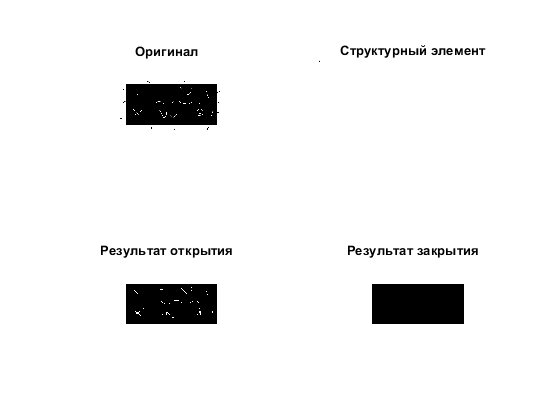

clc
clear all

I = imread('reck.jpg');
I = rgb2gray(I);
t = graythresh(I);

A = imbinarize(I,t);
A = ~A;
[nrows, ncols, ~] = size(A);


figure
subplot(2,2,1);
imshow(I);
title('Оригинал')

B = strel('rectangle',[15 15]); % получить монохромный круглый элемент
M = B.Neighborhood; % 
M(nrows, ncols) = 0;

subplot(2,2,2);
imshow(~M);
title('Структурный элемент')

Opening = imopen(A,B);
subplot(2,2,3);
imshow(~Opening);
title('Результат открытия')

Closing = imclose(Opening,B);
subplot(2,2,4)
imshow(~Closing)
title('Результат закрытия')

**Базовые морфологические операции на примере эллипса**

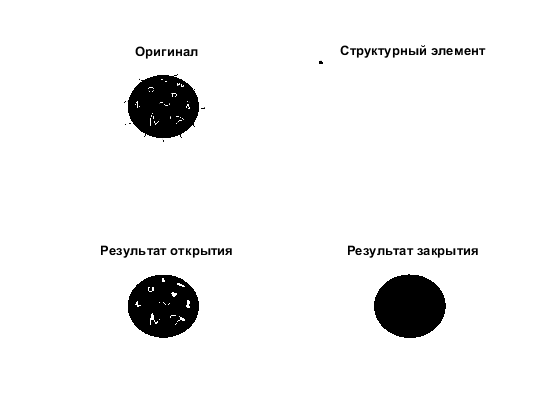

I = imread('original.jpg');
I = rgb2gray(I);
t = graythresh(I);

A = imbinarize(I,t);
A = ~A;
[nrows, ncols, layers] = size(A);


figure
subplot(2,2,1);
imshow(I);
title('Оригинал')

B = strel('disk',19,8); % получить монохромный круглый элемент
M = B.Neighborhood; % 
M(nrows, ncols) = 0;

subplot(2,2,2);
imshow(~M,[]);
title('Структурный элемент')

Opening = imopen(A,B);
subplot(2,2,3);
imshow(~Opening);
title('Результат открытия')

Closing = imclose(Opening,B);
subplot(2,2,4);
imshow(~Closing);
title('Результат закрытия')

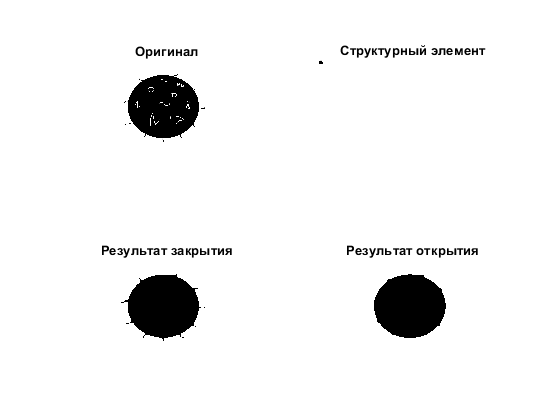

I = imread('original.jpg');
I = rgb2gray(I);
t = graythresh(I);

A = imbinarize(I,t);
A = ~A;
[nrows, ncols, layers] = size(A);


figure
subplot(2,2,1);
imshow(I);
title('Оригинал')

B = strel('disk',19,8); % получить монохромный круглый элемент
M = B.Neighborhood; % 
M(nrows, ncols) = 0;

subplot(2,2,2);
imshow(~M);
title('Структурный элемент')

Closing = imclose(A,B);
subplot(2,2,3);
imshow(~Closing);
title('Результат закрытия')

Opening = imopen(Closing,B);
subplot(2,2,4);
imshow(~Opening);
title('Результат открытия')

**Разделение объектов**

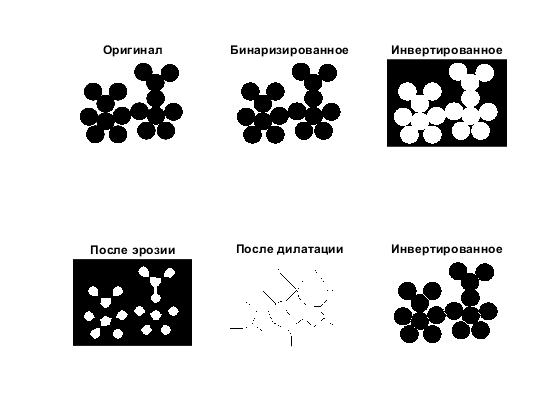

figure
I = imread('crs.jpg');
subplot(2,3,1);
imshow(I)
title('Оригинал')

I = rgb2gray(I);
t = graythresh(I);
Inew = imbinarize(I,t);
subplot(2,3,2);
imshow(Inew);
title('Бинаризированное')

Inew = ~Inew;
subplot(2,3,3);
imshow(Inew);
title('Инвертированное');

BW2 = bwmorph(Inew,'erode',20); % применяем морфологическую операцию эрозии 20 раз
subplot(2,3,4);
imshow(BW2);
title('После эрозии')

BW2 = bwmorph(BW2,'thicken', Inf); % утолщаем границы
subplot(2,3,5);
imshow(BW2)
title('После дилатации')

Inew = ~ (Inew & BW2);
subplot(2,3,6);
imshow(Inew);
title('Инвертированное')

**Сегментация изображения**

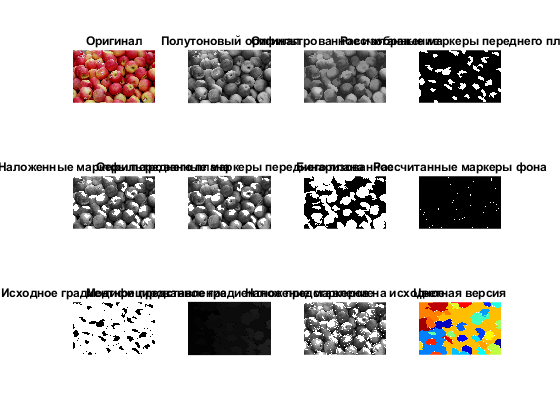

I = imread('apples.jpg');

figure

subplot(3,4,1)
imshow(I)
title('Оригинал')

A = rgb2gray(I);

subplot(3,4,2);
imshow(A);
title('Полутоновый оригинал')

B = strel('disk',18); % задаём наш структурный элемент. Объекты круглые, потому диск
C = imerode(A,B); % применяет операцию эрозии к А элементом В
Cr = imreconstruct(C,A); % делаем морфологическую реконструкцию 
Crd = imdilate(Cr, B); % операция дилатации
Crdr = imreconstruct(imcomplement(Crd), imcomplement(Cr)); % делаем реконструкцию, а
% внутри скобок вычисляется инвертированное изорбражение к аргументу
Crdr = imcomplement(Crdr);

subplot(3,4,3);
imshow(Crdr);
title('Отфильтрованное изображение')

fgm = imregionalmax(Crdr); % определяем локальные максимумы для определения
% маркеров переднего плана - foreground markers == fgm
subplot(3,4,4);
imshow(fgm);
title('Рассчитанные маркеры переднего плана')

A2 = A;
A2(fgm) = 255;
subplot(3,4,5);
imshow(A2)
title('Наложенные маркеры переднего плана')

B2 = strel(ones(5,5));
fgm = imclose(fgm,B2); % закрытие
fgm = imerode(fgm,B2); % эрозия
fgm = bwareaopen(fgm,10); % удаляем мелкие объекты, которые меньше заданного числа
A3 = A;
A3(fgm) = 255; 
subplot(3,4,6);
imshow(A3);
title('Отфильтрованные маркеры переднего плана');

bw = imbinarize(Crdr); % бинаризуем отфильтрованное изображение
subplot(3,4,7);
imshow(bw);
title('Бинаризованное');

D = bwdist(bw); % евклидово расстояние от каждого чёрного до ближайшего белого пикселя
L = watershed(D); % получаем сегменты методом водораздела
bgm = L == 0; % вычисляем значения матрицы 
subplot(3,4,8);
imshow(bgm)
title('Рассчитанные маркеры фона');

hy = fspecial('sobel'); % задаём фильтр Собела
hx = hy; 
Ay = imfilter(double(A), hy, 'replicate'); % применяем его
Ax = imfilter(double(A), hx, 'replicate');
grad = sqrt(Ax.^2 + Ay.^2); % вычисляем значение градиента
grad = imimposemin(grad, bgm | fgm); % определяем локальные минимумы изображения
subplot(3,4,9)
imshow(grad);
title('Исходное градиентное представление');

L = watershed(grad); % сегментация на уточненном градиентном представлении
subplot(3,4,10);
imshow(L);
title('Модифицированное градиентное представление')

A4 = A;
A4(imdilate(L == 0, ones(3,3)) | bgm | fgm) = 255;
subplot(3,4,11);
imshow(A4);
title('Наложение маркеров на исходное');

Lrgb = label2rgb(L,'jet', 'w', 'shuffle');
subplot(3,4,12);
imshow(Lrgb);
title('Цветная версия')

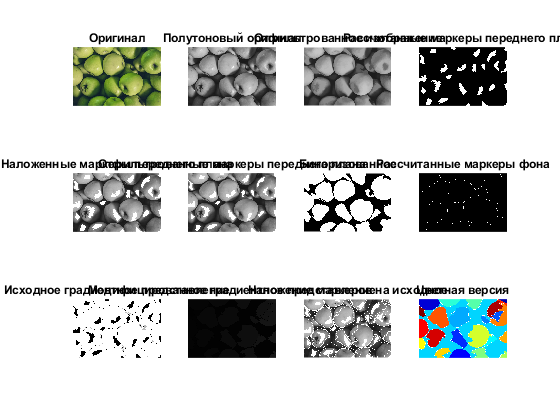

I = imread('green_apples.jpg');

figure

subplot(3,4,1)
imshow(I)
title('Оригинал')

A = rgb2gray(I);

subplot(3,4,2);
imshow(A);
title('Полутоновый оригинал')

B = strel('disk',15); % задаём наш структурный элемент. Объекты круглые, потому диск
C = imerode(A,B); % применяет операцию эрозии к А элементом В
Cr = imreconstruct(C,A); % делаем морфологическую реконструкцию 
Crd = imdilate(Cr, B); % операция дилатации
Crdr = imreconstruct(imcomplement(Crd), imcomplement(Cr)); % делаем реконструкцию, а
% внутри скобок вычисляется инвертированное изорбражение к аргументу
Crdr = imcomplement(Crdr);

subplot(3,4,3);
imshow(Crdr);
title('Отфильтрованное изображение')

fgm = imregionalmax(Crdr); % определяем локальные максимумы для определения
% маркеров переднего плана - foreground markers == fgm
subplot(3,4,4);
imshow(fgm);
title('Рассчитанные маркеры переднего плана')

A2 = A;
A2(fgm) = 255;
subplot(3,4,5);
imshow(A2)
title('Наложенные маркеры переднего плана')

B2 = strel(ones(5,5));
fgm = imclose(fgm,B2); % закрытие
fgm = imerode(fgm,B2); % эрозия
fgm = bwareaopen(fgm,10); % удаляем мелкие объекты, которые меньше заданного числа
A3 = A;
A3(fgm) = 255; 
subplot(3,4,6);
imshow(A3);
title('Отфильтрованные маркеры переднего плана');

bw = imbinarize(Crdr); % бинаризуем отфильтрованное изображение
subplot(3,4,7);
imshow(bw);
title('Бинаризованное');

D = bwdist(bw); % евклидово расстояние от каждого чёрного до ближайшего белого пикселя
L = watershed(D); % получаем сегменты методом водораздела
bgm = L == 0; % вычисляем значения матрицы 
subplot(3,4,8);
imshow(bgm)
title('Рассчитанные маркеры фона');

hy = fspecial('sobel'); % задаём фильтр Собела
hx = hy; 
Ay = imfilter(double(A), hy, 'replicate'); % применяем его
Ax = imfilter(double(A), hx, 'replicate');
grad = sqrt(Ax.^2 + Ay.^2); % вычисляем значение градиента
grad = imimposemin(grad, bgm | fgm); % определяем локальные минимумы изображения
subplot(3,4,9)
imshow(grad);
title('Исходное градиентное представление');

L = watershed(grad); % сегментация на уточненном градиентном представлении
subplot(3,4,10);
imshow(L);
title('Модифицированное градиентное представление')

A4 = A;
A4(imdilate(L == 0, ones(3,3)) | bgm | fgm) = 255;
subplot(3,4,11);
imshow(A4);
title('Наложение маркеров на исходное');

Lrgb = label2rgb(L,'jet', 'w', 'shuffle');
subplot(3,4,12);
imshow(Lrgb);
title('Цветная версия')